# 2025-26-ex-parcial-q1

# Problem 1

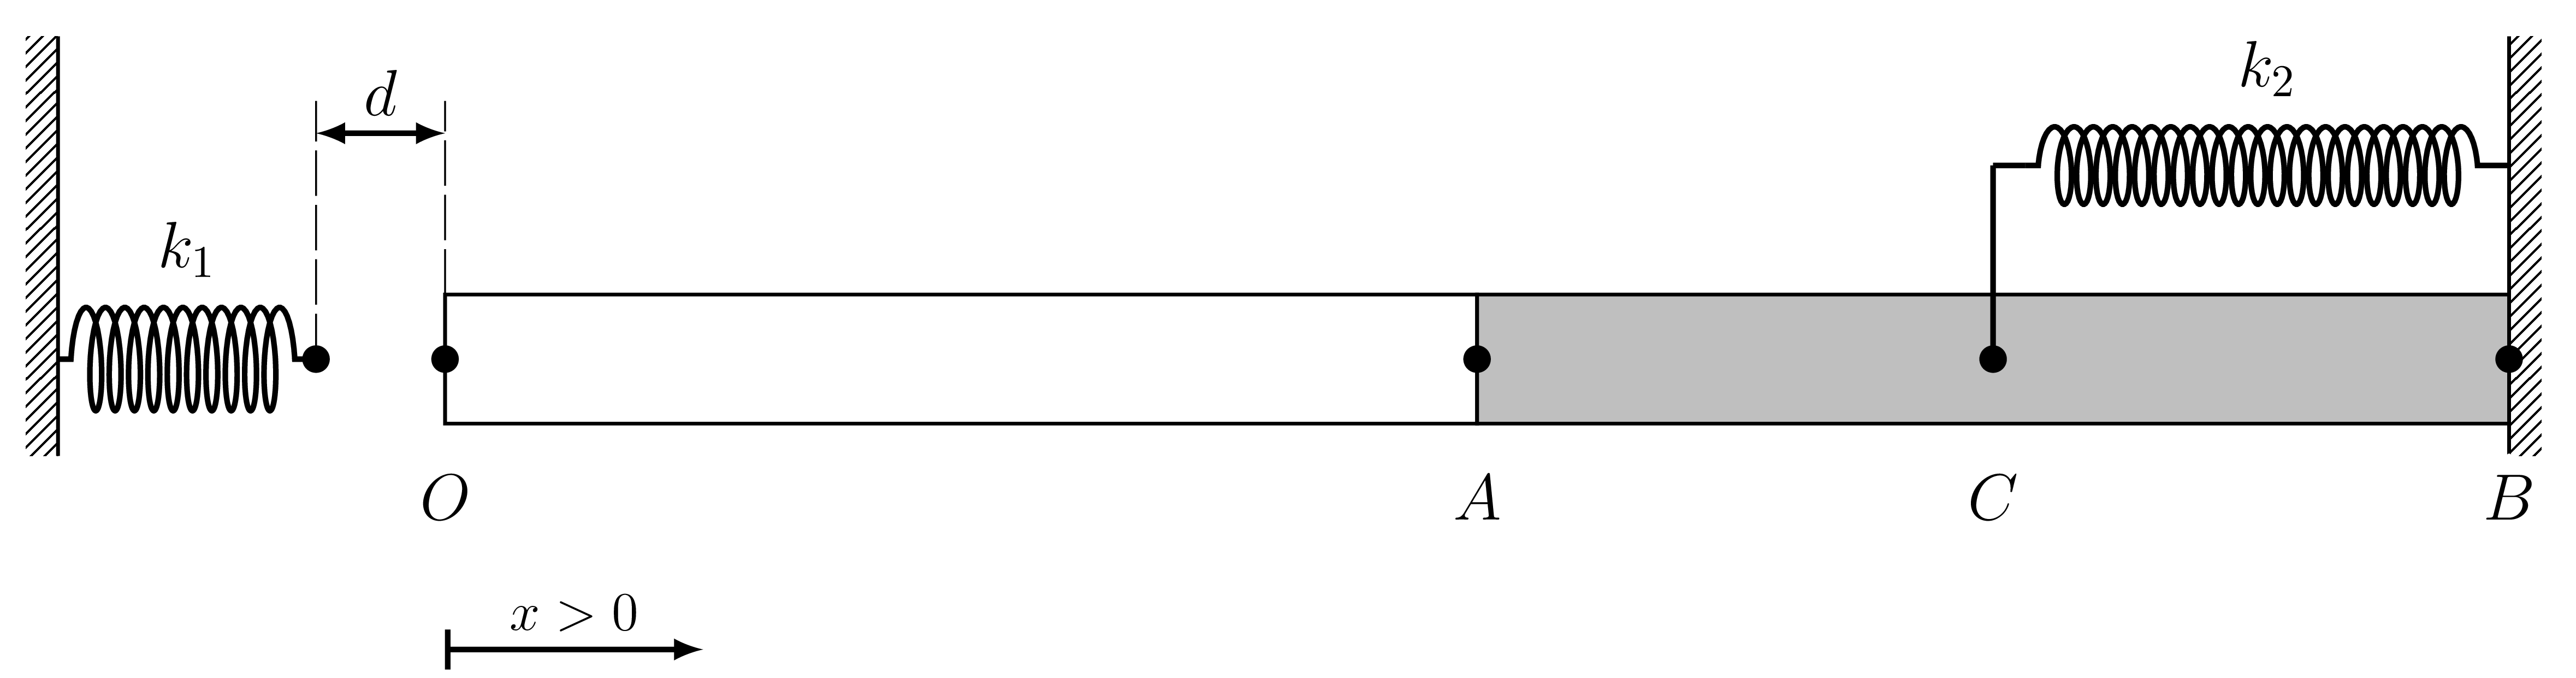

Consider the horizontal bar shown in the figure, with length (in the appropriate units) $L = 2\pi$and cross-sectional area $A_{s} = 3.0$; its right end is fixed to the wall.  We place the origin of coordinates at the left end of the bar (point 𝑂), so that the 𝑥 values increase to the right. The Young’s modulus, 𝐸, of the material forming the bar depends on $x$ according to the formula:


$$E(x) = \begin{cases}
       \pi\left( 2 + \cos x\right),& 0\le x < \pi,\\ 
\pi, & \pi\le x \le 2\pi.
\end{cases}$$


The springs are initially relaxed. The spring attached to the wall on the left has a stiffness constant $k_{1} = 1.0$, and its right end is located at a distance $d = 1.0$ from the left end of the bar (point $O$). The spring attached to the wall on the right has a stiffness constant $k_{2} = 3.0$ and is connected to the midpoint, point $C$, of segment $\overline{AB}$ (see the Figure).

We want to study the deformation of the bar when the spring on the left is connected to the end $O$. To do this, we will use the finite element method with two elements of length $h = \pi$: the first one linear, the second quadratic, located respectively over segments $\overline{OA}$ and $\overline{AB}$ of the Figure. The first global node is placed at point $O$, and the subsequent nodes are numbered in ascending order towards the right. Under these conditions, the following is requested:

## Part (a)

(3 points) The components of $K_{3,3}$ of the global stiffness matrix

- 17

- 13

- 19

- 14

- 16 ✅

- Leave it empty (no penallty)

- 15

- 18

**Hint.** The trace of the stiffness matrix is $\mathop{tr} K = 42$.

### Solution

#### Computation of the local stiffness matrix of element $\Omega^{1}$


$$\begin{array}{rcl} 
K^{1} =  K^{1,1}_{i,j}\hspace{-8pt} &=&\hspace{-8pt}\int_{x^{1}_{1}}^{x^{2}_{1}}
           a_{1}(x) \frac{\mathrm{d}\psi^{1}_{i}}{\mathrm{d} x}(x)
           \frac{\mathrm{d}\psi^{1}_{j}}{\mathrm{d} x}(x)\:\mathrm{d} x
           = \frac{(-1)^{i+j}}{h^{2}_{1}}\int_{x^{1}_{1}}^{x^{2}_{1}}\!\!
             A E(x) \: \mathrm{d} x \\
      \hspace{-8pt}&=&\hspace{-8pt} \pi A \frac{(-1)^{i+j}}{\pi^{2}}\int_{0}^{\pi}\!\!
              \left(2 + \cos(x)\right)\:\mathrm{d} x
            = 6 (-1)^{i+j},
\end{array}$$


with $i,j = 1,2$; and where


$$\begin{array}{rclrrcr}
   \psi_{1}^{1}(x) \!\!\!\! & = &\!\!\!\! \frac{x - x_{2}^{1}}{x_{1}^{1} - x_{2}^{1}} = \frac{x - \pi}{0 - \pi} = 1 - \frac{x}{\pi}, &
   \text{ and } &  \frac{\mathrm{d}\psi_{1}^{1}}{ \mathrm{d} x} (x) \!\!\! &=& \!\!\!\!\! -\frac{1}{\pi},\\
   \psi_{2}^{1}(x) \!\!\!\! & = &\!\!\!\! \frac{x - x_{1}^{1}}{x_{2}^{1} - x_{1}^{1}} = \frac{x - 0}{\pi - 0} = \frac{x}{\pi}, &
   \text{ and } &  \frac{\mathrm{d}\psi_{2}^{1}}{ \mathrm{d} x}  (x) \!\!\! &=& \!\!\!\!\! \frac{1}{\pi}.
\end{array}$$


Therefore, 

$K^{1} = \left(\begin{array}{rr}
6 & -6\\
-6 & 6
\end{array}\right)$.

**Remark: **Note that $a_{0} (x) = 0$ for all $0\le x\le \pi$, so $K^{1,0} = 0$ and then $K^{1} = K^{1,1} + K^{1,0} = K^{1,1}$.

#### Computation of the stiffness matrix of element $\Omega^{2}$

As the coefficients $a_{1}(x) = A E(x) = A \pi = 3\pi$, $a_{0}(x) = 0$ for all $\pi\le x\le 2\pi$ (i.e., they are constant on the element $\Omega^{2}$), we can use the formulas for the stiffness matrix of quadratic elements shown in the slides, i.e.,


$$K^{e,1} = \frac{a_{1}^{e}}{3 h_{e}}\left(
\begin{array}{rrr}
 7 & -8 & 1 \\
 -8 & 16 & -8 \\
1 & -8 & 7
\end{array}\right),\quad \text{ and }\quad
K^{e,0} = \frac{a_{0}^{e} h_{e}}{30}\left(
\begin{array}{rrr}
 4 & 2 & -1 \\
 2 & 16 & 2\\
-1 & 2 & 4
\end{array}\right),$$


with $e = 2$, $h_{2} = \pi$, $a^{2}_{1} = 3\pi$, and $a^{2}_{0} = 0$. Hence


$$K^{2} = K^{2,1}=\left(\begin{array}{rrr}
 7 & -8 & 1 \\
 -8 & 16 & -8 \\
1 & -8 & 7
\end{array}\right),$$


and note that (see above remark) $K^{2,0} = 0$ since $a^{2}_{0} = 0$, and then $K^{2} = K^{2,1} + K^{2,0} = K^{2,1}$.

#### Global stiffnes matrix


$$K = \left(
\begin{array}{rrrr}
   6 & -6 & & \\
  -6 & 13 & -8 & 1\\
   & -8 & 16 & -8 \\
  & 1 & -8 & 7
\end{array}\right),$$


 so$K_{3,3} = 16$.

clearvars
close all
format short e
format compact

d = 1.0;     %Distance form the right tip of the left spring to the 
             %left end of the bar
A = 3.0;
k1 = 1.0;    %Left spring's stiffness constant 
k2 = 3.0;    %Right spring's stiffness constant 
xP = pi / 4; %Point where to interpolate the displacement in item (d)

nodes = [0; pi; 3*pi/2; 2*pi];
numNodes = size(nodes,1);

Computation of the global stiffness matrix $K$:

%Stiffness matrices
%Element 1
syms x;
Psi1 = @(x) [(x-nodes(2)) / (nodes(1) - nodes(2));
    (x-nodes(1)) / (nodes(2) - nodes(1))];
dPsi1 = diff(Psi1,x);

E1 = @(x) (pi*(2+cos(x)))

K1 = A*double(int(E1(x)*(dPsi1*dPsi1'),x,nodes(1),nodes(2)))
%Element 2
E2 = pi;
Psi2 = [@(x) (x-nodes(3)) * (x-nodes(4)) /...
    ((nodes(2)-nodes(3))*(nodes(2)-nodes(4)));
             (x-nodes(2)) * (x-nodes(4)) /... 
    ((nodes(3)-nodes(2))*(nodes(3)-nodes(4)));
             (x-nodes(2)) * (x-nodes(3)) /...
    ((nodes(4)-nodes(2))*(nodes(4)-nodes(3)))];

dPsi2 = diff(Psi2,x);

K2 = A*E2*double(int(dPsi2*dPsi2',x,nodes(2),nodes(4)))
% (a) K(3,3)
%

K = zeros(numNodes);
rows = [1,2]; cols = rows;
K(rows,cols) = K1;
rows = [2,3,4]; cols = rows;
K(rows,cols)= K(rows,cols)+K2;

Kini = K; %Save a copy of the raw stiffness matrix

Global stiffness matrix, $K=$

fprintf("%10.6f%10.6f%10.6f%10.6f\n",Kini')

(a) $K_{3,3}$ and $\mathop{Tr} K$:

fprintf(['(a) K_{3,3} = %10.6f\n ',...
         '   Hint. Tr K = %10.6f\n'], Kini(3,3), trace(Kini))

## Part (b)

(3 points) The displacement, $u_{2}$, of the point $A$

- -1.9847e-01

- -1.6936e-01

- -2.2429e-01

- Leave it empty (no penalty)

- -2.1380e-01

- -2.3079e-01

- -1.5088e-01

- -1.9095e-01 ✅

### Solució

#### Coupled system


$$\left(
\begin{array}{rrrr}
   6 & -6 & & \\
  -6 & 13 & -8 & 1\\
   & -8 & 16 & -8 \\
  & 1 & -8 & 7
\end{array}\right) 
\left(
\begin{array}{c}
 U_{1}\\
 U_{2}\\
 U_{3}\\
 U_{4}
\end{array}\right)
=
\left(
\begin{array}{c}
  Q_{1}\\
  Q_{2}\\
  Q_{3}\\
  Q_{4}
\end{array}
\right)
+
\left(
\begin{array}{c}
  F_{1}\\
  F_{2}\\
  F_{3}\\
  F_{4}
\end{array}
\right)$$


with $F_{i} = 0$, $i=1,2,3,4$; since the $f(x) = 0$ for $0\le x \le L = 2\pi$ on $\Omega^{1}$ and $\Omega^{2}$. Indeed, because:


$$\begin{array}{rcl}
   F_{1} \hspace{-5pt} & = & \hspace{-5pt} F^{1}_{1} = 0, \\
   F_{2} \hspace{-5pt} & = & \hspace{-5pt} F^{1}_{2} + F^{2}_{1} = 0,\\
   F_{3} \hspace{-5pt} & = & \hspace{-5pt} F^{2}_{2} = 0,\\
   F_{4} \hspace{-5pt} & = & \hspace{-5pt} F^{2}_{3} = 0.
\end{array}$$


For, recall that

    
$$F_{i}^{e} = \int_{x_{1}^{e}}^{x_{N_{e}}^{e}} \psi^{e}_{i}(x) f(x)\,\mathrm{d} x,$$


for $i = 1,\dots,N_{e}$, being $N_{e}$ the number of nodes of the element  $\Omega^{e}$. For this case in point $e = 1$ and $N_{1} = 2$.

#### Boundary Conditions

- Natural B.C.: $Q_{1} = - k_{1} (d + U_{1})$ (see Remark below), $Q_{2} = 0$, $Q_{3} = -k_{2}U_{3}$; with $d = 1, k_{1} = 1$, and $k_{2} = 3$:


$$Q_{1} = -(1 + U_{1}),\qquad Q_{2} = 0, \qquad Q_{3} = 3 U_{3}.$$


- Essential B.C.: $U_{4} = 0$.

**Remark: **Note that, 

- If $-d < U_{1} < 0$, the spring stretches from its rest position a length $0 < d + U_{1}  < d$ to the right, thus the corresponding force acts to the left. Hence, by Hooke's law$Q_{1} = -k_{1}( d + U_{1} )$.

- If $U_{1} < -d_{1} < 0$, the spring shrinks from its rest position a length $-(d + U_{1}) > 0$ to the left, thus the corresponding force acts to the right. Hence, by Hooke's law, and again $Q_{1} = -k_{1}( d + U_{1} )$.

- If $U_{1} > 0$, the spring stretches from its rest position a length $d + U_{1}  > d$ to the right, thus the corresponding force acts to the left and hence, by Hooke's law, and yet again $Q_{1} = -k_{1}( d + U_{1} )$.

Therefore, $Q_{1} = -k_{1} ( d + U_{1} )$ whatsoever $U_{1}$.

#### Reduced system


$$\left(\begin{array}{rrr}
6 & -6  & 0\\
-6 & 13 & -8\\
0 & -8 & 16
\end{array}
\right)
\left(\begin{array}{c}
U_{1}\\
U_{2}\\
U_{3}
\end{array}\right)
=
\left(
\begin{array}{c} 
-k_{1} (  d + U_{1} )\\
0\\
-k_{2} U_{3}
\end{array}
\right) -
\left(\begin{array}{r}
0\\
1\\
-8
\end{array}
\right) U_{4}

\Longleftrightarrow

\left(\begin{array}{crc}
6 + k_{1} & -6  & 0\\
-6 & 13 & -8\\
0 & -8 & 16 + k_{2}
\end{array}
\right)
\left(\begin{array}{c}
U_{1}\\
U_{2}\\
U_{3}
\end{array}\right)
=
\left(
\begin{array}{c} 
-k_{1}  d\\
0\\
0
\end{array}
\right)
\quad
\text{  (since $U_{4} = 0$), }$$


and for $d = 1, k_{1} = 1$, and $k_{3} = 3$ the (reduced) system to solve is

$\left(
\begin{array}{rrr}
  7 & -6 & 0\\
  -6 & 13 & -8\\
  0 & -8 & 19
\end{array}
\right)
\left(
\begin{array}{c}
U_{1}\\
U_{2}\\
U_{3}
\end{array}
\right)
= 
\left(
\begin{array}{r}
-1\\
0\\
0
\end{array} 
\right)
$.

We seek this system solution by Cramer's rule. First, compute the determinants:


$$\begin{array}{rclrclrclrclrcl}
\Delta \!\!\!\! & = & \!\!\!\!
\left|\begin{array}{rrr}
7 & -6 & 0\\
-6 & 13 & -8\\
0 & -8 & 19
\end{array}
\right| = 
 7\times 13\times 19 - 64\times 7 - 36\times 19
 = 597, & &
\Delta_{1}\!\!\!\! & = &
\!\!\!\!
\left|\begin{array}{rrr}
-1 & -6 & 0\\
0 & 13 & -8\\
0 & -8 & 19
\end{array}
\right| \!\!\!\! 
& = & \!\!\!\! 
-\left|\begin{array}{rr}
13 & -8\\
-8 & 19
\end{array}
\right|
\!\!\!\!  & = & \!\!\!\! -183\\
\Delta_{2} \!\!\!\! & = & \!\!\!\!
\left|\begin{array}{rrr}
7 & -1 & 0\\
-6 & 0 & -8\\
0 &  0 & 19
\end{array}
\right| 
=
\left|\begin{array}{rr}
-6 & -8\\
0 & 19
\end{array}
\right| = 
-114, & &
\Delta_{3}\!\!\!\! & = &
\!\!\!\!
\left|\begin{array}{rrr}
7 & -6 & -1\\
-6 & 13 & 0\\
0 & -8 & 0
\end{array}
\right| \!\!\!\!
& = & \!\!\!\! 
-\left|\begin{array}{rr}
-6 & 13\\
 0 & -8
\end{array}
\right|
\!\!\!\!  & = & \!\!\!\! -48,
\end{array}
$$


so the components of the solution are,


$$\begin{array}{rclrclrcl}
U_{1}
\!\!\!\! & = & 
\!\!\!\!
 \frac{\Delta_{1}}{\Delta} 
 \!\!\!\! & = & 
\!\!\!\!
 - \frac{183}{597} 
\!\!\!\! & = & 
\!\!\!\!
 - \frac{3\times 61}{3\times 199} 
\!\!\!\! & = & 
\!\!\!\!
 - \frac{61}{199}  \approx  -3.0653\times 10^{-1}\\
 
U_{2}
\!\!\!\! & = & 
\!\!\!\!
 \frac{\Delta_{2}}{\Delta} 
 \!\!\!\! & = & 
\!\!\!\!
 - \frac{114}{597} 
\!\!\!\! & = & 
\!\!\!\!
 - \frac{3\times 38}{3\times 199} 
\!\!\!\! & = & 
\!\!\!\!
 - \frac{38}{199} \approx -1.9095\times 10^{-1},\\

U_{3}
\!\!\!\! & = & 
\!\!\!\!
 \frac{\Delta_{3}}{\Delta} 
 \!\!\!\! & = & 
\!\!\!\!
 - \frac{48}{597} 
\!\!\!\! & = & 
\!\!\!\!
 - \frac{3\times 16}{3\times 199} 
\!\!\!\! & = & 
\!\!\!\!
 - \frac{16}{199}
\approx -8.0402\times  10^{-2},\\

U_{4} \!\!\!\! & = & \!\!\!\! 0 &
& & & &
\end{array} 
$$


(the last one comes, $U_{4}  = 0$, comes straight from the boundary conditions).

% (b) u(3)
%

#### Boundary conditions

%Boundary conditions
fixedNodes = 4;
freeNodes= setdiff(1:numNodes, fixedNodes);
Q = zeros(numNodes,1);
u = zeros(numNodes,1);


#### Natural Boundary Conditions

%Natural B.C.
Q(1) = -k1*d;

#### Essential Boundary Conditions

%Essential B.C.
u(4) = 0.0;
%New global stiffness matrix that incorporates 
%the strings' strength
K(1,1) = K(1,1) + k1;
K(3,3) = K(3,3) + k2;


#### Modified stiffness matrix

fprintf("%10.6f%10.6f%10.6f%10.6f\n",K')

#### Reduced system, $(K_{m} | F_{m})$:

%Reduced system
Fm = Q(freeNodes) - K(freeNodes,fixedNodes)*u(fixedNodes);
Km = K(freeNodes,freeNodes);

fprintf("%10.6f%10.6f%10.6f | %10.6f\n",[Km Fm]')

#### Solution of the reduced system:

%Solution of the reduced system
um = Km\Fm;

u(freeNodes) = um;

#### Displacement, $u_{2}$, of the point $A$

for i = 0:numNodes
    if i == 0
        fprintf("(b) The displacements of the nodes are:\n")
    else
        if i == 2
            fprintf("    u(%d) = %s %c %.4e * Displacement of point A *\n", ...
                i, strtrim(rats(u(i))),char(8776),u(i))
        else 
            fprintf("    u(%d) = %s %c %.4e\n",i, strtrim(rats(u(i))),char(8776),u(i))
        end
    end
end 

## Part (c)

(2 points) The value of $Q_{1}$

- -6.9347e-01 ✅

- -6.6008e-01

- -6.8415e-01

- -6.9944e-01

- -6.8339e-01

- -7.1009e-01

- Leave it empty (no penalty)

- -6.7232e-01

**Hint.** The value of $Q_{3}$ is $Q_{3} =$ 2.4121e-01.

### Solution

#### Reaction forces of the springs


$$\begin{array}{lrcl}
\text{ Spring $1$ (left): }  & Q_{1} \!\!\!\! & = & \!\!\!\!F_{\text{Spring}_{1}} \!\!\!\! & = & \!\!\!\! - k_{1} \left( U_{1} + d \right)  = 
-1.0 \times \left( 1 - \frac{61}{199} \right)  =
-\frac{138}{199} \approx 
-6.9347\times 10^{-1},\\
\text{ Spring $2$ (right): } & Q_{3}\!\!\! & = & \!\!\!\! F_{\text{Spring}_{2}} \!\!\!\! & = & \!\!\!\! - k_{2} U_{3} = -3 \left(-\frac{16}{199}\right) = \frac{48}{199}
\approx 
2.4121\times 10^{-1}.
\end{array}
$$


#### **Post Process **

$Q = K U - F
\Longleftrightarrow 
Q =
\left(
\begin{array}{c}
Q_{1}\\
Q_{2}\\
Q_{3}\\
Q_{4}
\end{array}
\right) = 

-\frac{1}{199}
\left(
\begin{array}{rrrr}
6 & -6 & &\\
-6 & 13 & -8 & 1\\
& -8 & 16 & -8\\
& 1 & -8 & 7
\end{array}
\right)
\left(
\begin{array}{c}
61\\
38\\
16\\
0
\end{array}
\right) -
\left(
\begin{array}{c}
0\\
0\\
0\\
0
\end{array}
\right) =
-\frac{1}{199}
\left(
\begin{array}{c}
138\\
0\\
48\\
90
\end{array}
\right)
$,

% (c) Reaction forces of the springs: Q1 and Q3
% Post process

#### Post Process

Q = Kini * u;
fprintf("(c) Post process Q = K U - F:\n")
for nod = 1:numNodes
    if abs(Q(nod)) < 1.0e-14
        Q(nod) = 0;
    end
    if nod == 1 | nod == 3
        fprintf("Q(%d) = %s %c %.4e (*)\n", nod,strtrim(rats(Q(nod))),char(8776),Q(nod))
    else
        fprintf("Q(%d) = %s %c %.4e\n", nod,strtrim(rats(Q(nod))),char(8776),Q(nod))
    end
end

## Part (d) 

(2 points) The displacement (interpolated from the values of the element's nodes' displacements it belongs to) of the point $P$, located at $x_{P} = \pi / 4$

- -2.3151e-01

- -2.7764e-01 ✅

- Leave it empty (no penalty)

- -3.2410e-01

- -3.1442e-01

- -2.7235e-01

- -2.3700e-01

- -2.4911e-01

### Solution

#### Interpolated value of $u$ at $\pi / 4$:


$$u(\pi/4) \approx U^{1} (\pi / 4) =  U_{1}^{1}\psi_{1}^{1}(\pi / 4) + U_{2}^{1} \psi_{2}^{1}(\pi/4) = 
U_{1}\psi_{1}^{1}(\pi / 4) + U_{2}\psi_{2}^{1}(\pi/4)
=-\frac{61}{199}\times\left(1 - \frac{\pi / 4}{\pi}\right) - \frac{38}{199}\times\frac{\pi / 4}{\pi} = -\frac{3 \times 61 + 38}{4\times 199} =
-\frac{221}{796}
\approx
2.7764\times 10^{-1}.$$


% (d) Displacement at the point P, xP = pi / 4
%
uP = [u(1), u(2)]*Psi1(xP);
fprintf('(d) Interpolated value of u at pi/4, U(pi/4) = %s %c %.4e\n',...
    strtrim(rats(uP)),char(8776),uP)
% fprintf(['Solutions:\n',...
%     '(a) K_{3,3} = %10.6f\n ',...
%     '   Hint. Tr K = %10.6f\n',...
%     '(b) Displacement of point A, u(2) = %s %c %.4e\n',...
%     '(c) Reaction force of the leftmost spring,  R1 = %s %c %.4e\n',...
%     '    Hint. Reaction force of the rightmost spring, R2 = %s %c %.4e\n',...
%     '(d) Interpolated value of u at pi/4, U(pi/4) = %s %c %.4e\n'],...
%      Kini(3,3), trace(Kini),strtrim(rats(u(2))),char(8776),u(2),...
%      strtrim(rats(Fs1)),char(8776),Fs1,strtrim(rats(Fs2)),char(8776),Fs2,...
%      strtrim(rats(uP)),char(8776),uP)

fprintf(['Solutions:\n',...
    '(a) K_{3,3} = %10.6f\n ',...
    '   Hint. Tr K = %10.6f\n',...
    '(b) Displacement of point A, u(2) = %s %c %.4e\n',...
    '(c) Q(1) = %s %c %.4e\n',...
    '    Hint. Q(3) = %s %c %.4e\n',...
    '(d) Interpolated value of u at pi/4, U(pi/4) = %s %c %.4e\n'],...
     Kini(3,3), trace(Kini),strtrim(rats(u(2))),char(8776),u(2),...
     strtrim(rats(Q(1))),char(8776),Q(1),strtrim(rats(Q(3))),char(8776),Q(3),...
     strtrim(rats(uP)),char(8776),uP)